# RockPaperScissors 

Imports 455180 rounds of rock-paper-sissors games in the file

[https://justincollier.com/wp-content/uploads/2016/05/Rock_Paper_Scissors_Raw.xlsx.](https://justincollier.com/wp-content/uploads/2016/05/Rock_Paper_Scissors_Raw.xlsx.)

The data was collected by an [online free game](https://roshambo.me/ ) . A [claim](https://justincollier.com/life-hacks/how-to-win-rock-paper-scissors/) is *Rock is thrown 37.7% of the time as a first throw in a game. By  contrast, the least commonly thrown option, Scissors, is only thrown first 27.8% of the time. Throwing paper first more likely will beat your opponent’s first throw (Rock) while hedging against the less commonly thrown Scissor.* 

The data appear in sequential groups of games (player pairs) with a few rounds per game with players moves (rock, paper, or scissors) denoted (I assume) by 1, 2, or 3. Sometimes 0 appears, presumably because one player sent the link to another and made a move and the other failed to respond or the other player responded after the first gave up. 

We find the fraction of first-of-the-round moves of each type to see if they are random or not ignoring whether both players moved or just one. And we evaluate the statistical significance of the results to see if the claim is justified by the data.

You can click the Run arrow in the Live Editor or start (recommended) by clicking the bar at the left of the next section.

Author: D. Carlsmith

## Import the data

Let's learn how MATLAB can read data right from a web link. Create a character array holding the [URL](https://en.wikipedia.org/wiki/URL) for the data and read the data into a table with [webread](https://www.mathworks.com/help/matlab/ref/webread.html). This takes several seconds.

data_url='https://justincollier.com/wp-content/uploads/2016/05/Rock_Paper_Scissors_Raw.xlsx'

data_url = 'https://justincollier.com/wp-content/uploads/2016/05/Rock_Paper_Scissors_Raw.xlsx'

datatable=webread(data_url);

[Save data as spreadsheet file](https://www.mathworks.com/help/matlab/import_export/exporting-to-excel-spreadsheets.html) with [writetable](https://www.mathworks.com/help/matlab/ref/writetable.html). I would  recommend against opening the spreadsheet file in a spreadsheet program (it may crash the program) but you can double-click it in the current folder pane in MATLAB to view it and check the contents are the same as what you find double-clicking the table form.

writetable(datatable,'rockpaperscissor.xlsx');

Convert table to array with [table2array](https://www.mathworks.com/help/matlab/ref/table2array.html).

data=table2array(datatable);

Each row has a game id, and round id, and a throw number. Presumably a game is a match between players and a round is a seqence of paired throws until someone wins. The throw values are 0,1,2,3. We will presume 0 means no throw. For example, player 1 throws but player 2 left the game or never even joined. 1 means rock, 2 mean paper, 3 means scissor. 

Convert imported array to column vectors with descriptive names. This is a best practice so the code tells you what it is doing.

gameID = data(:,1);
gameRoundID = data(:,2);
player_one_throw = data(:,3);
player_two_throw = data(:,4);

## Begin analysis

If you run this Live Script section by section, you can skip the time-consuming import section.

Delete any prior figures.

delete(findall(0,'Type','figure'))

First plot the data, starting with the first variable, to look for patterns and irregularities.

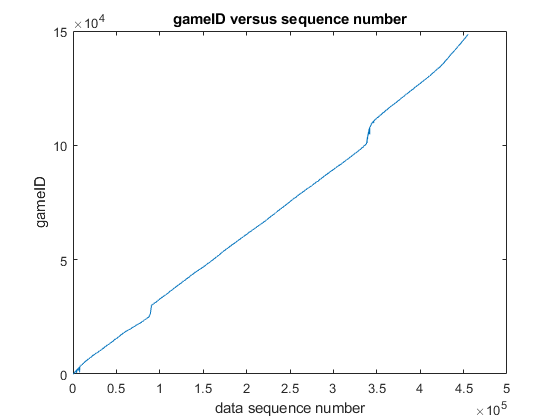

plot(gameID)
title('gameID versus sequence number')
xlabel('data sequence number');ylabel('gameID')

The gameID is not strictly monatonic but this oddity appears a small fraction of the time. 

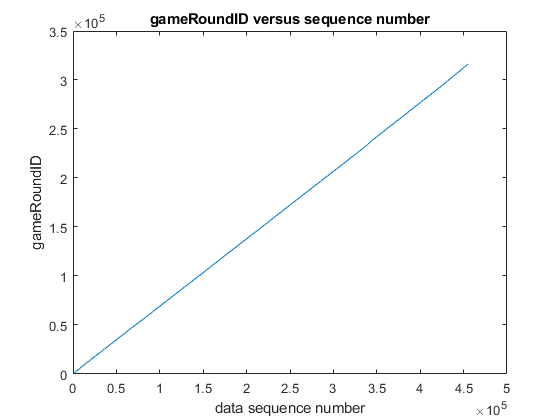

figure
plot(gameRoundID)
title('gameRoundID versus sequence number')
xlabel('data sequence number');ylabel('gameRoundID');

The gameRoundID is monatomic so a better counter. We will ignore gameID and use gameRoundID. 

Let's look at some data. We define a range of indices with a name (`range`) and then use that range variable name. This is a best practice. If we want to change the range, we change it in one place and the change propogates through the code.

range=1:20;

Use [disp](https://www.mathworks.com/help/matlab/ref/disp.html) to display numbers prettier than just letting MATLAB print out values of variables.

disp( [gameID(range),gameRoundID(range),...
    player_one_throw(range), player_two_throw(range)])

     1     1     1     1
     1     1     2     3
     1     2     3     2
     1     3     1     1
     1     3     1     2
     1     4     2     3
     2     5     1     0
     3     6     1     1
     3     6     2     1
     3     7     3     3
     4     8     1     3
     4     9     3     2
     4    10     2     2
     4    10     1     1
     4    10     3     3
     4    10     3     3
     4    10     2     2
     4    10     3     3
     4    10     3     2
     5    11     1     1



In the first game, first round, both played rock and tied, then paper and scissor and scissor won. In the 2nd round, they played scissor and paper and player 1 won. In the 3rd round, it was rock v rock for a tie and rock v paper and player 1 won. In the 4th round, it was paper v scissor and player 2 won. These players then quit the game. Within game 4 between players, there were three rounds. The first two lasted one throw. The second lasted 7 throws! Typically there are but one or two rounds and one or two throws per round.

Let's look at the runs in the data using  [diff](https://www.mathworks.com/help/matlab/ref/diff.html). The command `y=diff(x)`  calculates the difference between adjacent elements of `x` creating a vector `y` with one less element.  `y` will vanish during a run.

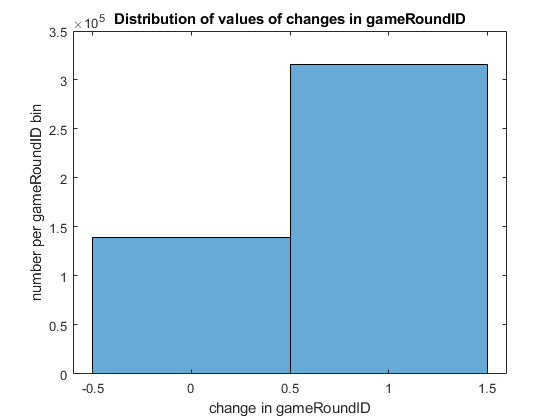

diff_gameRoundID=diff(gameRoundID);
histogram(diff_gameRoundID)
title('Distribution of values of changes in gameRoundID')
xlabel('change in gameRoundID')
ylabel('number per gameRoundID bin')

The values are all 0 or 1 implying  `gameRoundID` either doesn't change or increases by 1. Good.

Get indices to places where the gameRoundID is about to change using [find](https://www.mathworks.com/help/matlab/ref/find.html).

indices= find(diff_gameRoundID>0);

Print out the values for our peek-a-boo range of indices.

indices(range)

ans =      2
     3
     5
     6
     7
     9
    10
    11
    12
    19


The difference in index values is the length of the round.

round_lengths = diff(indices);

Plot the lengths of the rounds.

figure
nbins=50;
histogram(round_lengths, nbins)

Set the y-axis to log scale since the distribution has a long tail and a wide range of values.

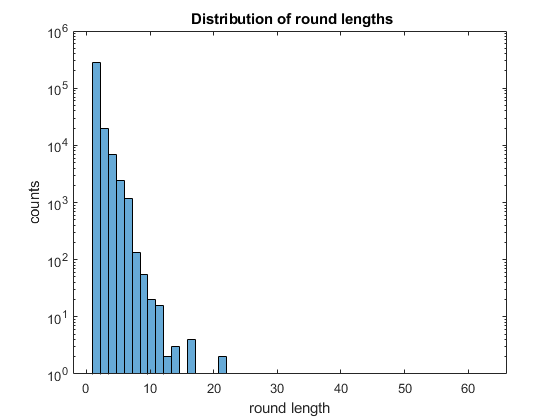

set(gca,'YScale','log')
xlabel('round length');ylabel('counts')
title(' Distribution of round lengths')

Most rounds last one throw. This distribution has a long tail. The histogram choses an encompassing range so there must be some bins with just one entry per bin. Let's find the length of the maximal one using [max](https://www.mathworks.com/help/matlab/ref/max.html).

max_round_length=max(round_lengths)

max_round_length = 63

Let's pull out the index where that crazy round occurs using [find](https://www.mathworks.com/help/matlab/ref/find.html).

max_round_length_start_index = find(round_lengths==max_round_length)

max_round_length_start_index = 20416

Now print out the crazy round starting just one round before and going a bit after

istart=indices(max_round_length_start_index);
iend = istart+max_round_length;
ibit = 10;
iend=iend+ibit;
disp( [gameID(istart:iend),gameRoundID(istart:iend),...
    player_one_throw(istart:iend), player_two_throw(istart:iend)])

        9620       20416           3           2
        9621       20417           1           1
        9621       20417           1           1
        9621       20417           1           1
        9621       20417           1           1
        9621       20417           1           1
        9621       20417           1           1
        9621       20417           1           1
        9621       20417           1           1
        9621       20417           1           1
        9621       20417           1           1
        9621       20417           1           1
        9621       20417           1           1
        9621       20417           1           1
        9621       20417           1           1
        9621       20417           1           1
        9621       20417           1           1
        9621       20417           1           1
        9621       20417           1           1
        9621       20417           1           1
        9621       2

Hah, hah. This could be two people constantly playing rock v rock until player 1 broke down and played paper. But they kept going with their game for a few normal rounds afterwards.

Now let's look at the number of games by making a vector containing all instances of positive change in gameRoundID and then using [length](https://www.mathworks.com/help/matlab/ref/length.html) to find the length of that vector. Not thhat `length` works for vectors but you generally want `size` for arrays.

ngames=length(diff_gameRoundID(diff_gameRoundID>0))

ngames = 316293

The number of games is 70% of the number of rounds. As we hzave seen, the number of rounds is usually 1, sometimes 2 or 3. The choices are RR, RP, RS, PR, PP, PS,SR, SP, SS so if selected at random, 1/3 of games should last 1 round.

Histogram the throw number of Player 1 for all rounds.

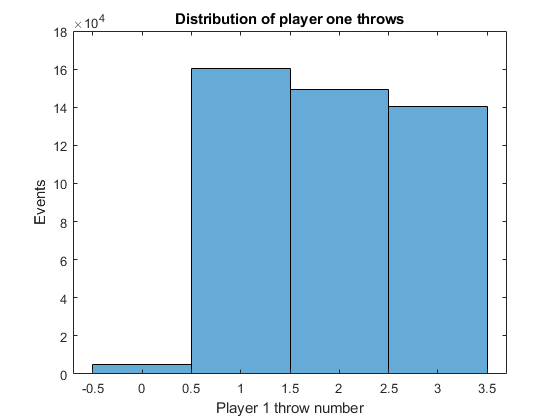

figure
histogram(player_one_throw)
title('Distribution of player one throws')
xlabel('Player 1 throw number');ylabel('Events')

Player 1 appears to favor rock over paper by a factor 1.06 and to disfavor scissor by a similar factor, and sometimes quits before throwing. This is averaged over all throws.

Histogram the player 2 throws.

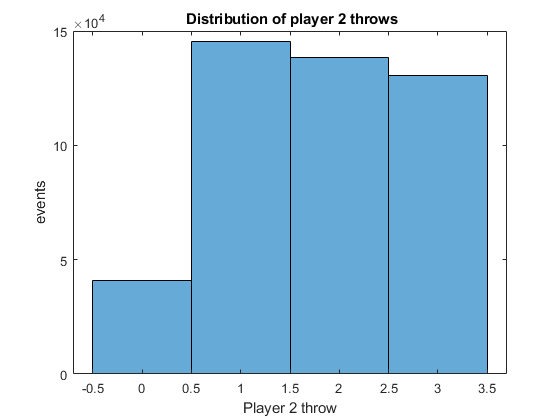

figure
histogram(player_two_throw)
xlabel('Player 2 throw');ylabel('events');
title(' Distribution of player 2 throws')

[nnz](https://www.mathworks.com/help/matlab/ref/nnz.html)`(x) `is the number of nonvanishing elements of x. `length(x) `is the number of elements of x. The fraction of nonvanishing player two throws is

nnz(player_two_throw)/length(player_two_throw)

ans = 0.9105

About 9% of the time, player 2 seems to decline to play. It looks like player 1 initiates the game, invites player 2, and throws. Player 2 may not be interested 8% of the time after checking it out or become unavailable. But most of the time, player 2 is game to play and also leads with 'rock'  more than 33% of the time.

The following 3d view shows the correlations. Select view camera toolbar and select 'orbit camera' from the toolbar to explore. 

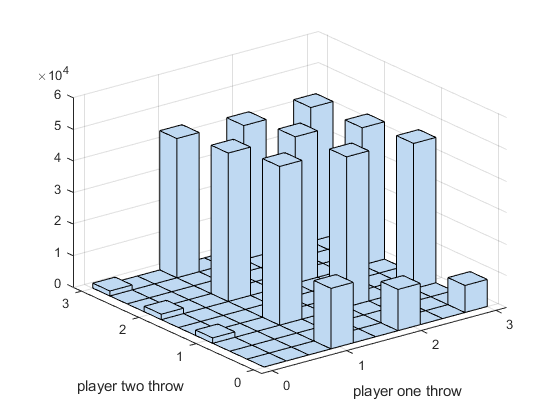

figure
hist3([player_one_throw player_two_throw])
xlabel('player one throw')
ylabel('player two throw')

Note the number of throws in the dataset is nearly 1/2 million.

nthrows=length(player_one_throw)

nthrows = 455180

## Start extracting needed information

Get indices of first occurances of each sequential `gameRoundID` as a vector `ia` using the MATLAB [unique](https://www.mathworks.com/help/matlab/ref/unique.html) command rather than using the differencing technique. These indices point to the first rounds of all of the games. This could also be done with an explicit loop over rounds checking for an increment in gameRoundID.

[C, ia, ic] = unique(gameRoundID,'stable');
nrounds=length(ia)

nrounds = 316294

`C` contains the unique gameRoiundID values. `ia(k)` is the index in gameRoundID of the first of the k-th unique gameRoundID runs. The number of unique rounds is the length of `ia`. 

Get the number of unique rounds with nonvanishing values for player 1.  Note that sometimes player 1 was awaiting player 2 before throwing and player 2 never showed up.

nrounds_unique1 = length(ia(player_one_throw(ia)>0 ))

nrounds_unique1 = 312514

Get the number of times player 1 leads with 'rock', 'paper', or 'scissor'.

nlead1(1)=length(player_one_throw(player_one_throw(ia)==1));
nlead1(2)=length(player_one_throw(player_one_throw(ia)==2));
nlead1(3)=length(player_one_throw(player_one_throw(ia)==3));
nlead1

nlead1 =       112804      104838       94872


Check the fractions add up.

(nlead1(1)+nlead1(2)+nlead1(3))/nrounds_unique1

ans = 1

Repeat for player two.

nrounds_unique2 = length(ia(player_two_throw(ia)>0 ));
nlead2(1)=length(player_two_throw(player_two_throw(ia)==1));
nlead2(2)=length(player_two_throw(player_two_throw(ia)==2));
nlead2(3)=length(player_two_throw(player_two_throw(ia)==3));
nlead2

nlead2 =        96047       94324       86407


(nlead2(1)+nlead2(2)+nlead2(3))/nrounds_unique2

ans = 1

(nlead2(1)+nlead2(2)+nlead2(3))/nrounds_unique1

ans = 0.8856

It appears player 2 shows up and responds 11% of the time for cases in which player 1 invited and ALSO made a throw.

Compute fraction of times player 1 leads with 'rock', and the error assuming a [binomial distribution](https://en.wikipedia.org/wiki/Binomial_distribution) and using the measured fraction in the error estimate. And similarly for player 2.

mean1 = nlead1./nrounds_unique1

mean1 =     0.3610    0.3355    0.3036


std1 = (nrounds_unique1^(-1)*mean1.*(1-mean1)).^(1/2)

std1 = 	1.0e+-3 *

    0.8591    0.8446    0.8225


mean2 = nlead2./nrounds_unique2

mean2 =     0.3470    0.3408    0.3122


std2 = (nrounds_unique2^(-1)*mean2.*(1-mean2)).^(1/2)

std2 = 	1.0e+-3 *

    0.9048    0.9009    0.8808


We find similar but not the same means quoted in the blog. It appears the invited player (presumably player 2, like the inviting player player 1, leads with rock more often than random chance, but 4% (relatively) less so than the invited player. In view of the estimated errors, this difference between the order of the players in leading with 'rock' is small but statistically significant.

Compare the difference for players 1 and 2 and the combined error assuming the players are independent.

diff = mean1-mean2

diff =     0.0139   -0.0053   -0.0086


diffstd = (std1.^2+std2.^2).^(1/2)

diffstd =     0.0012    0.0012    0.0012


diff./diffstd

ans =    11.1712   -4.3132   -7.1462


It could be people who  found the website and invited another person (who might not be so into it) have a slightly higher tendency then their invitees to lead with rock. It could also be that player 1 is always the player who invites and that player 2 more likely assumes player 1 has already moved and hence tends to think player one has played rock so plays paper.

## Conclusions

Both players favor rock over paper over scissors slightly in this data set.

The difference between players in the online game in favoring rock are a fraction of the difference between fraction rock is first played and the value 1/3 expected if players led with a random choice. 

This sample of games is an unknown and quite possibly unrepresentative sample of offline players of rock-paper-scissor.